# GFDM System Simulation

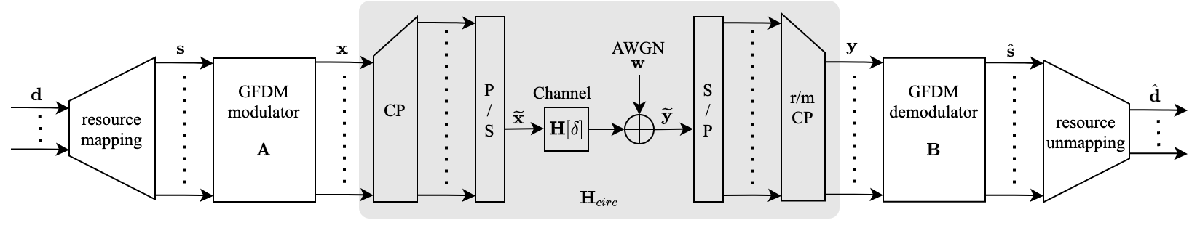

CLEAN_RUN = false;
if CLEAN_RUN
    clear; clc; clf; %#ok<UNRCH>
end

DEBUG = false;  % Plot some figures

addpath(genpath('prototype filter'));

Simulation parameters.

conste_size = 4;                        % Size of signal constellation (QPSK)
bits_per_sym = log2(conste_size);       % Bits per symbol
Es = 1;                                 % Symbol energy
EbNo = (0:2:20);                        % Eb/N0(dB)
SNR = EbNo + 10*log10(bits_per_sym);    % Convert Eb/N0 to SNR(dB)
CHANNEL = "AWGN";

N_trial = 1e3; % Number of Monte Carlo trials

GFDM parameters.

gfdm = struct;

gfdm.equalizer = "ZF";

gfdm.pulse = "dirichlet"; % Pulse shape
gfdm.CP = 0;    % CP length

gfdm.K = 8; % Subcarriers
gfdm.M = 7; % Subsymbols

gfdm.K_set = (1:3); % Used subcarrier index(1 based)
gfdm.M_set = (2:gfdm.M);       % Used subsymbol index(1 based). 1 guard subsymbol.

gfdm.K_on = numel(gfdm.K_set); % Number of used subcarriers
gfdm.M_on = numel(gfdm.M_set); % Number of used used subsymbols

gfdm.D = gfdm.K*gfdm.M;       % Number of elements
gfdm.N = gfdm.K_on*gfdm.M_on; % Used elements

Channel.

% Power delay profile
switch CHANNEL
    case "AWGN"
        h_dB = 0;
    case "LTI"
        h_dB = [0 -Inf -Inf -3 -Inf -Inf -Inf -Inf -Inf -5];
end

% Channel impulse response
h = db2mag(h_dB)';

% Channel frequency response
% FFT size = gfdm.D + gfdm.CP?
H_k = fft(h, gfdm.D + gfdm.CP); % no normalization

% Circulant matrix
C_circ = circulant_matrix(h, gfdm.D);

if DEBUG
    figure   %#ok<UNRCH>
    stem(h)
    set(gca, 'yscale', 'log');
    xlim([0, 11]); ylim([0.5, 1.1]);
end

Prototype filter, GFDM modulator, and characteristic matrix.

% Prototype filter
switch gfdm.pulse
    case "dirichlet"
        gfdm.g = dirichlet(gfdm.M, gfdm.K);
    case "rc"
        gfdm.g = rc(gfdm.M, gfdm.K);
    case "rrc"
        gfdm.g = rrc(gfdm.M, gfdm.K);
end

% GFDM modulator(transmitter matrix)
% A == (kron(W_M', eye(gfdm.K)) * diag(G(:)) * kron(W_M, W_K'))
A = g2A(gfdm.g, gfdm.K, gfdm.M);


% M-point DFT matrix
W_M = (1/sqrt(gfdm.M))*dftmtx(gfdm.M);
% K-point DFT matrix
W_K = (1/sqrt(gfdm.K))*dftmtx(gfdm.K);

% Characteristic matrix
gfdm.G = sqrt(gfdm.D) * reshape(gfdm.g, gfdm.K, gfdm.M) * W_M;

if DEBUG
    % Plot A matrix
    X = 1:gfdm.D;    %#ok<UNRCH>
    figure;
    surf(X, X, abs(A));
    set (gca, 'ydir', 'reverse');   % Flip Y axis
    title('abs(A)');
    %     figure;
    %     surf(X, X, real(A));
    %     set (gca, 'ydir', 'reverse');
    %     title('real(A)');
    %     figure;
    %     surf(X, X, imag(A));
    %     set (gca, 'ydir', 'reverse');
    %     title('imag(A)');
end

Monte Carlo simulation.

% BER estimation
ber_est = zeros(size(EbNo));

% Start timer
tic

for n = 1:length(EbNo)
    % Reset error counter
    num_err = 0;
    
    for trial_idx = 1:N_trial
        % ---------- Tx ----------
        % Generate random data
        bin_data = randi([0, 1], bits_per_sym, gfdm.N)';
        dec_data = bi2de(bin_data, 'left-msb');
        
        % QPSK mapping
        qpsk_data = pskmod(dec_data, conste_size, pi/conste_size, 'gray');   % QPSK modulation with Gray coding
        % Normalize symbol energy
        % qpsk_data_norm = (Es^0.5) * norm(qpsk_data(1)) * (qpsk_data);
        
        % Debug. Plot QPSK data:
        if DEBUG && (n == 1)
            scatterplot(qpsk_data), grid;
            title('Constellation');
        end
        
        % Resource mapping
        resource_map_data = resource_map(gfdm, qpsk_data);
        % resource_map_data_matrix = reshape(resource_map_data, gfdm.K, gfdm.M);
        
        % GFDM modulation
        % gfdm_data = A * resource_map_data;
        gfdm_data = gfdm_mod(gfdm, resource_map_data);
        
        % Cyclic prefix
        cp_data = add_cp(gfdm, gfdm_data);
        
        % Parallel to serial
        tx_sig = reshape(cp_data, 1, []);
        
        % ------- Channel --------
        channel_out = conv(tx_sig, h);
        
        % Remove the part of the signal that was spread by the channel
        channel_out_remove_spread = channel_out(1: end-length(h)+1);
        
        % AWGN noise
        rx_sig = awgn(channel_out_remove_spread, SNR(n));
        
        % ---------- Rx ----------
        %Serial to parallel
        rx_parallel = reshape(rx_sig, [], 1);
        
        % Remove cyclic prefix
        rx_rm_cp_data = remove_cp(gfdm, rx_parallel);
        
        % GFDM demodulation
        rx_demod_data = A \ rx_rm_cp_data;
        % rx_demod_data = gfdm_demod(gfdm, rx_rm_cp_data);
        
         % Resource unmapping
        rx_resource_unmap = resource_unmap(gfdm, rx_demod_data);
        % rx_resource_unmap_matrix = reshape(rx_resource_unmap, gfdm.K, gfdm.M);
        
        % QPSK demodulation
        rx_dec_data = pskdemod(rx_resource_unmap, conste_size, pi/conste_size, 'gray');
        
        % Convert symbols to bits
        rx_bin_data = de2bi(rx_dec_data, bits_per_sym, 'left-msb');
        
        % Calculate the number of bit errors
        nErrors = biterr(bin_data, rx_bin_data);
        
        % Increment the error counter
        num_err = num_err + nErrors;
    end
    
    % Estimate BER
    ber_est(n) = num_err/(N_trial * gfdm.N * bits_per_sym);
end

% End timer
toc

Plot PSD.

% TODO

Plot the estimated and theoretical BER data.

% Theoretical BER
berQPSK = berawgn(EbNo', 'psk', conste_size, 'nondiff');

% Plot
figure;
semilogy(EbNo, ber_est, '-*');
hold on;
grid;
semilogy(EbNo, berQPSK);
% legend('GFDM', 'QPSK');
% legend('$\mathcal{|K|}$ = 8', '$\mathcal{|K|}$ = 6', '$\mathcal{|K|}$ = 3', 'Interpreter','latex');
ylabel('BER');
ylim([10^(-6), 10^(-1)]);
xlabel('E_b/N_0 (dB)');

function s = resource_map(p, d)
% Map data vector d onto (K, M) resource matrix S.
% Returns vec(S).

s_matrix_idx = false(p.K, p.M);
s_matrix_idx(p.K_set, p.M_set) = true;

s = zeros(p.D, 1);
s(s_matrix_idx) = d;

% s_matrix = reshape(s, p.K, p.M); 
end

function d = resource_unmap(p, s)
% Unmap data vector d from (K, M) resource matrix S.
% S = reshape(s, K, M).

s_matrix_idx = false(p.K, p.M);
s_matrix_idx(p.K_set, p.M_set) = true;

d = s(s_matrix_idx);
end

function x_cp = add_cp(p, x)
cp_matrix = [zeros(p.CP, p.D-p.CP) eye(p.CP); eye(p.D)];
x_cp = cp_matrix * x;
end

function y = remove_cp(p, y_cp)
remove_cp_matrix = [zeros(p.D, p.CP) eye(p.D)];
y = remove_cp_matrix * y_cp;
end

function gfdm_data = gfdm_mod(p, data)
data_matrix = reshape(data, p.K, p.M);
gfdm_data_temp = (sqrt(p.K)) * ifft(data_matrix, [], 1);
gfdm_data_temp = (1/sqrt(p.M)) * fft(gfdm_data_temp, [], 2);
gfdm_data_temp = p.G .* gfdm_data_temp;
gfdm_data_temp = (sqrt(p.M)) * ifft(gfdm_data_temp, [], 2);
gfdm_data = gfdm_data_temp(:);
end

function gfdm_demod_data = gfdm_demod(p, data)
data_matrix = reshape(data, p.K, p.M);

switch p.equalizer
    case "ZF"
        % TODO
    case "MMSE"
        % TODO
end
end